Loopback calibration

In this section, you can calibrate a measured spectrum using a "loopback" structure.Objective:

- remove the baseline shape of the grating couplers

Method:

- curve-fit the spectrum of two grating couplers (or an MZI with ∆L=0) using a low-order polynomial

- Restrict to ~10 dB from peak to avoid using data with a large error

- Subtract this polynomial from subsequent data

You can download and run the [Matlab code](https://s3.amazonaws.com/edx-course-phot1x-chrostowski/Phot1x/data_loopback_calibration.m) on your own computer. 

Use the Matlab code below to download and plot the measurement data.

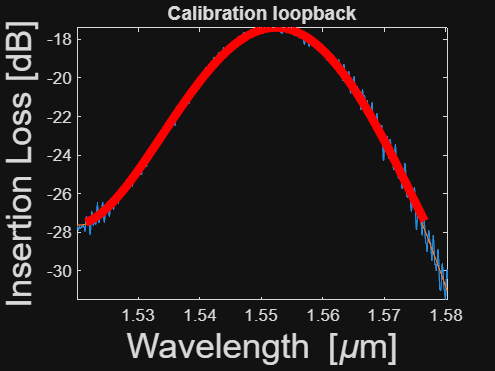


% Read data files from experiments
% Enter the Dropbox URLs here.  Make sure the URL has a =1 at the end:
%  Loopback structure:
url_loopback = 'https://www.dropbox.com/s/w915qfix9kwlwv7/ZiheGao_MZI1_272_Scan1.mat?dl=1';
%  MZI:
url_mzi = 'https://www.dropbox.com/s/1rvjfef4jqybc12/ZiheGao_MZI2_271_Scan1.mat?dl=1';
% Calibrate the MZI data using the loopback structure
% Plot


PORT=1; % Which Fibre array port is the output connected to?
FONTSIZE=20;


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Loopback data:
a=websave('loopback.mat',url_loopback); % get data from Dropbox
load('loopback.mat');
% Data is stored in variable "scanResults".
% There are two columns - wavelength (1), and amplitude (2)
lambda=scanResults(1,PORT).Data(:,1)/1e9;
amplitude=scanResults(1,PORT).Data(:,2);
figure;
plot (lambda*1e6, amplitude);
title ('Calibration loopback'); 
xlabel ('Wavelength [\mum]','FontSize',FONTSIZE)
ylabel ('Insertion Loss [dB]','FontSize',FONTSIZE)
hold all;

% Fit the data with a polynomial
p=polyfit((lambda-mean(lambda))*1e6, amplitude, 5);
amplitude_LOOPBACK=polyval(p,(lambda-mean(lambda))*1e6);
plot (lambda*1e6, amplitude_LOOPBACK);
% find wavelength range with usable data, in the loopback
loopback_IL = max(amplitude);
new_lambda_i=find(amplitude>loopback_IL-10);
lambda=lambda(new_lambda_i);
lambda_min = min(lambda);
lambda_max = max(lambda);
amplitude=amplitude(new_lambda_i);
% refit the loopback
LOOPBACK=polyfit((lambda-mean(lambda))*1e6, amplitude, 4);
amplitude_LOOPBACK=polyval(LOOPBACK,(lambda-mean(lambda))*1e6);
plot (lambda*1e6, [amplitude_LOOPBACK],'r-','Linewidth',5);
axis tight;

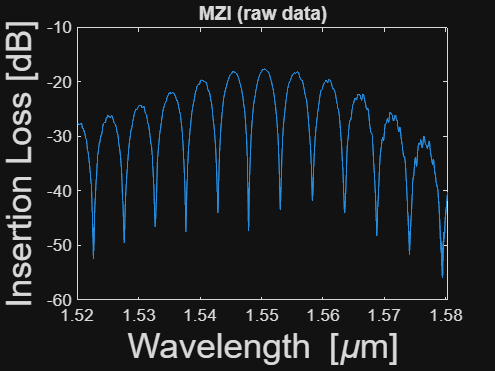



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% MZI data:
a=websave('mzi.mat',url_mzi); % get data from Dropbox
load('mzi.mat');
lambda1=scanResults(1,PORT).Data(:,1)/1e9;
amplitude=scanResults(1,PORT).Data(:,2);
figure;
plot (lambda1*1e6, amplitude);
title ('MZI (raw data)'); 
xlabel ('Wavelength [\mum]','FontSize',FONTSIZE)
ylabel ('Insertion Loss [dB]','FontSize',FONTSIZE)

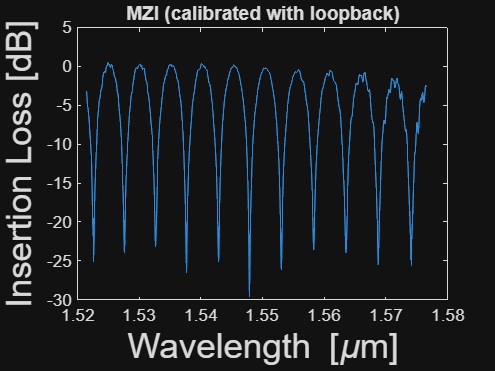


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% MZI data - calibrated
%
% data only within the bandwidth of interest.
lambda=lambda_min:min(diff(lambda1)):lambda_max;
amplitude=interp1(lambda1, amplitude, lambda,'linear');
amplitude(find(amplitude==-inf))=-50;
% calibrate data
amplitude_cal=amplitude-polyval(LOOPBACK,(lambda-mean(lambda))*1e6);
figure;
plot (lambda*1e6, amplitude_cal);
title ('MZI (calibrated with loopback)'); 
xlabel ('Wavelength [\mum]','FontSize',FONTSIZE)
ylabel ('Insertion Loss [dB]','FontSize',FONTSIZE)